clear;clc;close all;

fs = 10000;
T = 1/fs;
L = 10000;  % 信号长度
t = (0:L-1)*T;

x = sin(2*pi*50*t) + 0.2*sin(2*pi*150*t) + 0.05*randn(size(t));

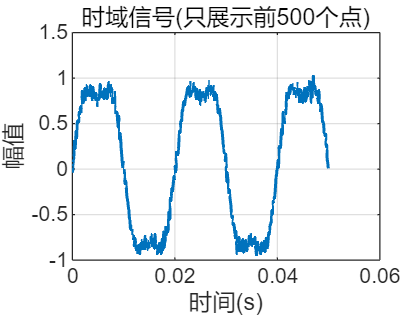

figure;
plot(t(1:500),x(1:500),'LineWidth',1.2)
grid on
xlabel('时间(s)')
ylabel('幅值')
title('时域信号(只展示前500个点)')

% 进行 FFT 变换
Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = fs*(0:(L/2))/L;

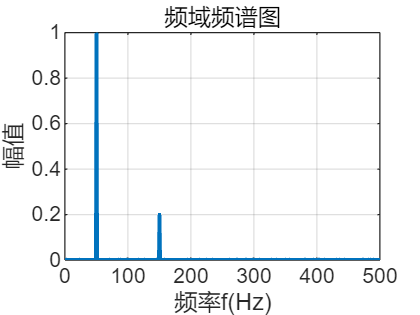

figure;
plot(f, P1, 'LineWidth', 1.5)
grid on
xlabel('频率f(Hz)')
ylabel('幅值')
title('频域频谱图')
xlim([0 500])  % 只看 0 到 500H